df_raw = load("\\wsl.localhost\Ubuntu\home\merlijn\projects\brain_computer_project\ass1\artefacts.mat")

df_raw = struct with fields:
    art: [120×23501 single]



df = df_raw.art

df = 120×23501 single matrix
    3.4503   -7.0766   -5.6607   -3.1376   -0.3729    1.2657   -2.8201    2.3525   15.6208   24.7359   16.2792   -1.1520    6.6818   15.2077    4.9019    0.0572   -9.7865  -28.8859  -26.7107  -12.9802   -6.4609   -4.8388  -15.3036  -20.1829  -18.9540  -15.1957    5.1017   10.0343   -9.1356    6.2597   28.4815    5.7002   -8.6162  -14.4915  -22.8277  -13.9759  -10.1751  -11.2743   -7.2434   -8.1461  -17.0400  -25.2681  -29.0224  -26.6746  -27.7695  -45.1659  -43.7548  -13.5530   -2.9182   -4.8241
   -2.5810   -8.2664   -3.1903    4.4202    8.2348    3.3193   -5.6564    1.2940   11.6009   14.9069    9.4474   -4.8010    0.6692    8.7986   -0.4968   -5.7796   -2.3369    0.0606   -0.9945   -5.8263  -10.8764  -14.0471  -19.6323  -17.1482  -19.6076  -21.6544   -1.8915    3.0724  -17.0047   -6.8915   17.5220    2.6776  -10.8604   -9.0119  -11.9693  -14.5467  -19.1217  -15.5831  -11.1102  -15.9731  -21.4800  -19.2663  -16.1781  -24.0086  -22.4480  -17.0830  -20.4335



idx_AFp1 = 4;   % Anterior to Fz
idx_FCz = 17;   % Posterior to Fz (also anterior to Cz)
idx_CPz = 27;   % Posterior to Cz (also anterior to Oz)
idx_POz = 37;   % Anterior to Oz
idx_Iz = 47;    % Posterior to Oz
idx_FZ = 12;
idx_CZ = 22;
idx_OZ = 42;

% Extract electrode data
AFp1 = df(idx_AFp1, :);
FCz = df(idx_FCz, :);
CPz = df(idx_CPz, :);
POz = df(idx_POz, :);
Iz = df(idx_Iz, :);
OZ = df(idx_OZ, :);
CZ = df(idx_CZ, :);
FZ = df(idx_FZ, :);
% Compute Bipolar Derivations
% Formula: Bipolar = Anterior channel - Posterior channel
bipolar_Fz = AFp1 - FCz;
bipolar_Cz = FCz - CPz;
bipolar_Oz = POz - Iz;

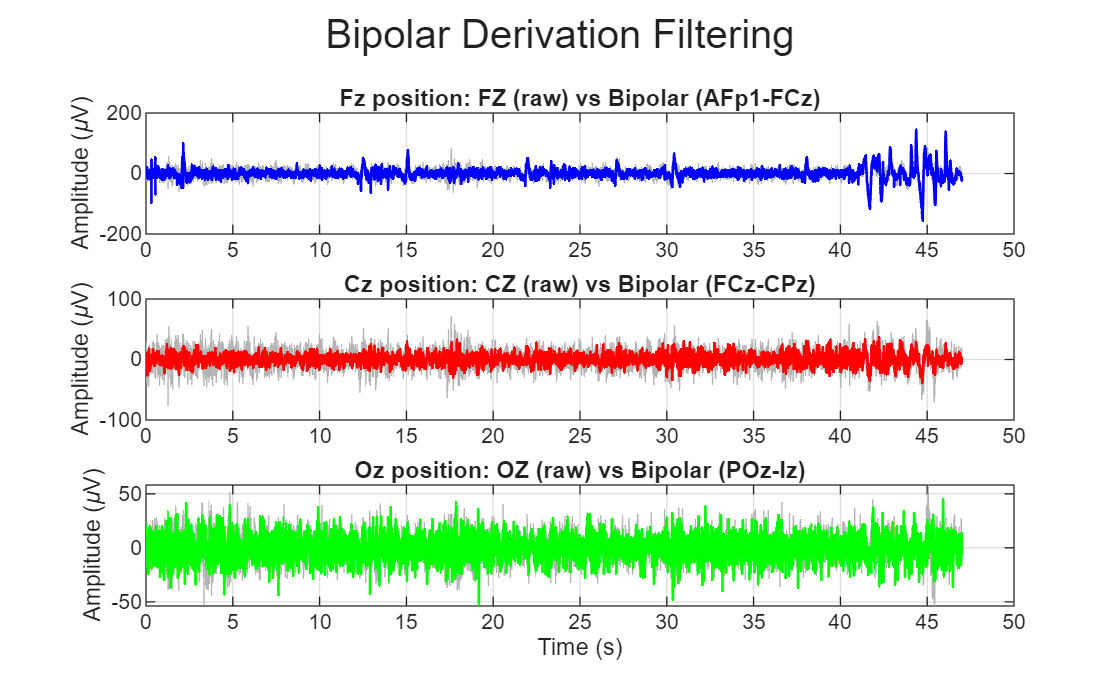

% Sampling rate
fs = 500;
% Create a time vector in seconds. Since sampling interval T = 1/fs, we need vector
% with intervals of 0.002 sec
t = (0:size(df, 2) - 1) / fs;
figure;
sgtitle('Bipolar Derivation Filtering');
% Plot Fz
subplot(3, 1, 1);
plot(t, FZ, 'Color', [0.7 0.7 0.7]); hold on;
plot(t, bipolar_Fz, 'b', 'LineWidth', 1);
title('Fz position: FZ (raw) vs Bipolar (AFp1-FCz)');
ylabel('Amplitude (\muV)');
grid on;
% Plot Cz
subplot(3, 1, 2);
plot(t, CZ, 'Color', [0.7 0.7 0.7]); hold on;
plot(t, bipolar_Cz, 'r', 'LineWidth', 1);
title('Cz position: CZ (raw) vs Bipolar (FCz-CPz)');
ylabel('Amplitude (\muV)');
grid on;
% Plot Oz
subplot(3, 1, 3);
plot(t, OZ, 'Color', [0.7 0.7 0.7]); hold on;
plot(t, bipolar_Oz, 'g', 'LineWidth', 1);
title('Oz position: OZ (raw) vs Bipolar (POz-Iz)');
xlabel('Time (s)');
ylabel('Amplitude (\muV)');
grid on;